# KNN algorithmn

% Load the data from social network file
Social_network = readtable("C:\Users\pc user\Documents\MATLAB\Classification\K-Nearest Neighbor\Social_Network_Ads.csv")

Social_network = 400×5 table
      UserID        Gender      Age    EstimatedSalary        Purchased    
    __________    __________    ___    _______________    _________________

    1.5625e+07    {'Male'  }    19           19000        {'Not Purchased'}
    1.5811e+07    {'Male'  }    35           20000        {'Not Purchased'}
    1.5669e+07    {'Female'}    26           43000        {'Not Purchased'}
    1.5603e+07    {'Female'}    27           57000        {'Not Purchased'}
    1.5804e+07    {'Male'  }    19           76000        {'Not Purchased'}
    1.5729e+07    {'Male'  }    27           58000        {'Not Purchased'}
    1.5598e+07    {'Female'}    27           84000        {'Not Purchased'}
    1.5695e+07    {'Female'}    32         1.5e+05        {'Purchased'    }
    1.5601e+07    {'Male'  }    25      

% check if there are missing values
ismissing(Social_network)

ans = 400×5 logical array
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0


% check for outliers
isoutlier(Social_network.Age)

ans = 400×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


isoutlier(Social_network.EstimatedSalary)

ans = 400×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


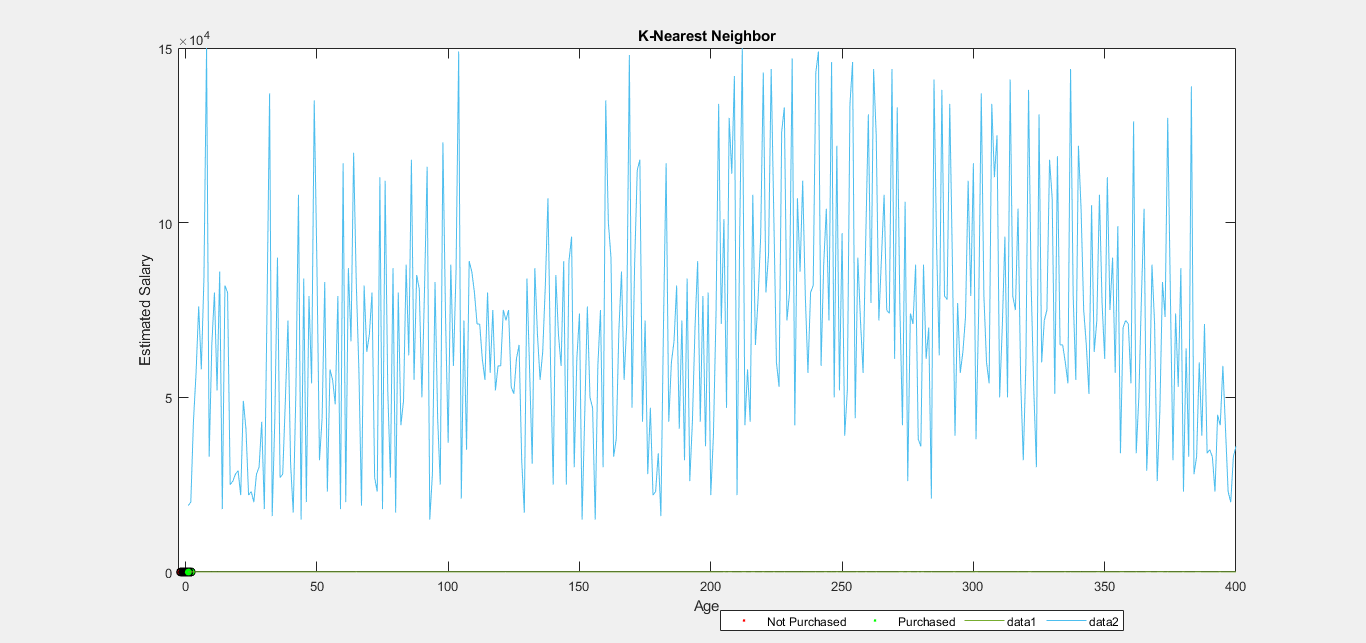

plot(Social_network.Age)
plot(Social_network.EstimatedSalary)

% Remove the userID column
Social_network.UserID = []

Social_network = 400×4 table
      Gender      Age    EstimatedSalary        Purchased    
    __________    ___    _______________    _________________

    {'Male'  }    19           19000        {'Not Purchased'}
    {'Male'  }    35           20000        {'Not Purchased'}
    {'Female'}    26           43000        {'Not Purchased'}
    {'Female'}    27           57000        {'Not Purchased'}
    {'Male'  }    19           76000        {'Not Purchased'}
    {'Male'  }    27           58000        {'Not Purchased'}
    {'Female'}    27           84000        {'Not Purchased'}
    {'Female'}    32         1.5e+05        {'Purchased'    }
    {'Male'  }    25           33000        {'Not Purchased'}
    {'Female'}    35           65000        {'Not Purchased'}
    {'Female'}    26           80000        {'Not Purchased'}
    {'Female'}    26        

## Feature Scaling

% We need to fit Age and Estimated Salary columns to same scale
stand_age = (Social_network.Age -mean(Social_network.Age))/std(Social_network.Age);
Social_network.Age = stand_age;
stand_estimatesalary = (Social_network.EstimatedSalary - mean(Social_network.EstimatedSalary))/std(Social_network.EstimatedSalary);
Social_network.EstimatedSalary = stand_estimatesalary;
Social_network

Social_network = 400×4 table
      Gender        Age       EstimatedSalary        Purchased    
    __________    ________    _______________    _________________

    {'Male'  }     -1.7796        -1.4882        {'Not Purchased'}
    {'Male'  }    -0.25327        -1.4589        {'Not Purchased'}
    {'Female'}     -1.1118       -0.78431        {'Not Purchased'}
    {'Female'}     -1.0164       -0.37371        {'Not Purchased'}
    {'Male'  }     -1.7796        0.18352        {'Not Purchased'}
    {'Male'  }     -1.0164       -0.34439        {'Not Purchased'}
    {'Female'}     -1.0164        0.41815        {'Not Purchased'}
    {'Female'}    -0.53945         2.3538        {'Purchased'    }
    {'Male'  }     -1.2072        -1.0776        {'Not Purchased'}
    {'Female'}    -0.25327       -0.13909        {'Not Purchased'}
    {'Female'}     -1.1118    

## Let's Build KNN Model

% KNN model
classification_model = fitcknn(Social_network,'Purchased ~ Age+EstimatedSalary');
classification_model

classification_model =   ClassificationKNN
           PredictorNames: {'Age'  'EstimatedSalary'}
             ResponseName: 'Purchased'
    CategoricalPredictors: []
               ClassNames: {'Not Purchased'  'Purchased'}
           ScoreTransform: 'none'
          NumObservations: 400
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


% Let's split the data into training and test data
cv = cvpartition(classification_model.NumObservations, 'HoldOut', 0.2);
cv

cv = Hold-out cross validation partition
   NumObservations: 400
       NumTestSets: 1
         TrainSize: 320
          TestSize: 80
          IsCustom: 0

% Let's build KNN model based on training data
cross_validation_model = crossval(classification_model, 'cvpartition',cv);
cross_validation_model

cross_validation_model =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'Age'  'EstimatedSalary'}
           ResponseName: 'Purchased'
        NumObservations: 400
                  KFold: 1
              Partition: [1×1 cvpartition]
             ClassNames: {'Not Purchased'  'Purchased'}
         ScoreTransform: 'none'


  Properties, Methods


## Predict the classifier on the testing set

% Predict on the testing set
Predictions = predict(cross_validation_model.Trained{1}, Social_network(test(cv),1:end-1));
Predictions

Predictions = 80×1 cell array
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Purchased'    }
    {'Not Purchased'}
    {'Not Purchased'}
    {'Purchased'    }
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Purchased'    }
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Purchased'    }
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}
    {'Not Purchased'}


## Analyze the predictions

% Let's use a Confusion Matrix
Results = confusionmat(cross_validation_model.Y(test(cv)), Predictions);
Results

Results =     42     9
     8    21


## Visualizing the KNN model results

% setting labels and classifier names
labels = unique(Social_network.Purchased);
classifier_name = 'K-Nearest Neighbor';

% computing the minimum and maximum Age and Salary
Age_range = min(Social_network.Age(training(cv))) -1:0.01:max(Social_network.Age(training(cv)))+1;
Estimated_salary_range = min(Social_network.EstimatedSalary(training(cv))) -1:0.01:max(Social_network.EstimatedSalary(training(cv)))+1;


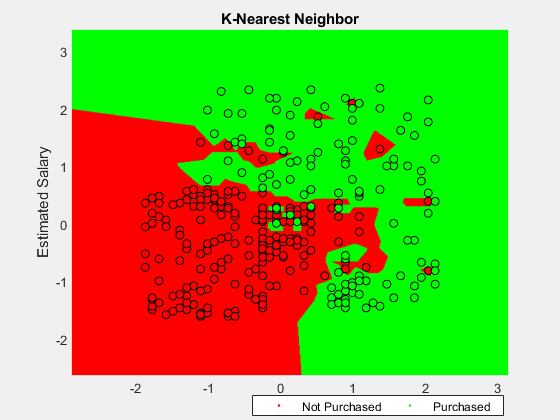

% Let's create 2D co-ordinates
[xx1, xx2] = meshgrid(Age_range,Estimated_salary_range);
XGrid = [xx1(:) xx2(:)];

% Create prediction meshgrid
predictions_meshgrid = predict(cross_validation_model.Trained{1},XGrid);

% Plot the predictions on the grid
figure;

gscatter(xx1(:), xx2(:), predictions_meshgrid, 'rgb');

hold on

training_data = Social_network(training(cv),:);
Y = ismember(training_data.Purchased,labels(1));

scatter(training_data.Age(Y), training_data.EstimatedSalary(Y), 'o', 'MarkerEdgeColor','black','MarkerFaceColor','red');
scatter(training_data.Age(~Y),training_data.EstimatedSalary(~Y), 'o', 'MarkerEdgeColor','black','MarkerFaceColor','green');

xlabel('Age');
ylabel('Estimated Salary');

title(classifier_name);
legend off;
axis tight;

legend(labels,'Location',[0.45,0.01,0.45,0.05],'Orientation','Horizontal');

% Let's bring the figure to the front
set(0, 'DefaultFigureVisible', 'on');

figure(gcf);
